# Saeed Niku Dynamics

Provided by Dr. Mohammad Hasan

Modifed by Kai De La Cruz 6/27/2025

Start by producing the A matrices (Forward Kinematics)

Also compute the J matrices (moment of inertia)

Then compute the U matrices (Derivatives of the A matrices)

Finally, compute the D matrices (inertia matrices)

Using all of these, we can compute the joint torques

To change this code, you only need to modify the following matrices:

- AStructure (to include additional frame transformations)

- JStructure (to include the inertia tensor of new object)

- rStructure (to include the location of the center of gravity relative to the frame)

- The theta_dot and theta_ddot vectors

In here, trajectory in generated using a third-order spline.

clear
clc

%Robot Parameters
g = 9.81; %magnitude of g
m1 = (2.76875*4.44822)/g; %Link 1 mass (2 motors and mounts)[kg]
m2 = 0.102 + 0.057; %Link 2 mass
m3 = 0.069; %Link 3 mass
L1 = 2.285 * 0.3048; % [m]
L2 = 4.77 * 0.3048;
L3 = 5.75 * 0.3048; 
L4 = 6.125 * 0.3048;


% Izz and Iyy were switched between CAD and Hand Calc
J1 =[0.001 0 0 0;
    0 0.001 -6.025e-5 0;
    0 -6.025e-5 0.002 0;
    0 0 0 1];    % shoulder link 1 inertia tensor [kg m^2]

% Ixx and Iyy were switched between CAD and Hand Calc
J2 = [9.474e-5 6.121e-5 1.23e-5 0;
    6.121e-5 0.001 -3.304e-6 0;
    1.23e-5 -3.304e-6 0.001 0;
    0 0 0 1]; % thigh link 2 inertia tensor [kg m^2]

% Rot by +45 deg about z-axis
J3 = [1.69e-6 -9.874e-8 -8.366e-9 0;
    -9.874e-8 0 1.949e-7 0;
    -8.366e-9 1.949e-7 0 0;
    0 0 0 1]; % lower leg link 3 inertia tensor [kg m^2]

JStructure = struct();
JStructure(1).Matrix = J1;
JStructure(2).Matrix = J2;
JStructure(3).Matrix = J3;

r1 = [0 ;0 ; L2/2 ;1]; %position of CoG of shoulder relative to frame 1. (constant)
r2 = [-L3/2 ;0 ;0 ;1]; %position of CoG of thigh relative to frame 2. (constant)
r3 = [-L4/2 ;0 ;0 ;1]; %position of CoG of LL relative to frame 3. (constant)

rStructure = struct();
rStructure(1).Matrix = r1;
rStructure(2).Matrix = r2;
rStructure(3).Matrix = r3;
m_vec = [m1, m2, m3]; %a vector storing the masses of each link 
g_vec = [g ;0 ;0 ;0]; %Velocity vector in frame 0 (here g is in the negative y direction)

%Generate the trajectory
% [Shoulder, Thigh, Lower Leg]
theta_i = [0 ; 0 ; 0] %starting joint angles [rad] 

theta_i =      0
     0
     0


theta_dot_i = [0 ; 0 ; 0] %starting joint velocities [rad/s]

theta_dot_i =      0
     0
     0


theta_f = [deg2rad(0) ; deg2rad(45) ; deg2rad(90)] %final joint angles (from inverse kinematics) [rad]

theta_f =          0
    0.7854
    1.5708


theta_dot_f = [0 ; 0 ; 0] %final joint velocities desired -- stop there [rad/s]

theta_dot_f =      0
     0
     0



T = 3; %trajectory duration
Coeff = GenerateTrajectory(theta_i, theta_dot_i, theta_f, theta_dot_f, T); %get cubic spline coefficients as a set in a 2x4 matrix
Coeff_v = [Coeff(:,2), 2*Coeff(:,3), 3*Coeff(:,4), zeros(length(theta_i),1)]; %from the cubic spline, you can find coefficients for joint velocity
Coeff_a = [2*Coeff(:,3), 6*Coeff(:,4), zeros(length(theta_i),1), zeros(length(theta_i),1)]; %and joint acceleration

t = linspace(0,3,100);

for ii=1:length(t)
    t_array = [1; t(ii); t(ii)^2; t(ii)^3];
    %compute and store theta1, theta1dot,theta1ddot, theta2, theta2dot,
    %theta2ddot (all from the chosen trajectory).
    theta1 = Coeff(1,:)*t_array;
    theta2 = Coeff(2,:)*t_array;
    theta3 = Coeff(3,:)*t_array;
    theta_dot_1 = Coeff_v(1,:)*t_array;
    theta_dot_2 = Coeff_v(2,:)*t_array;
    theta_dot_3 = Coeff_v(3,:)*t_array;
    theta_ddot_1 = Coeff_a(1,:)*t_array;
    theta_ddot_2 = Coeff_a(2,:)*t_array;
    theta_ddot_3 = Coeff_a(3,:)*t_array;
    
    % %Below is an example of a sine trajectory
    % theta1 = sin(0.2*2*pi*t(ii));
    % theta2 = sin(0.15*2*pi*t(ii));
    % theta_dot_1 = 0.2*2*pi*cos(0.2*2*pi*t(ii));
    % theta_dot_2 = 0.2*2*pi*cos(0.15*2*pi*t(ii));
    % theta_ddot_1 = -(0.2*2*pi)^2*sin(0.2*2*pi*t(ii));
    % theta_ddot_2 = -(0.2*2*pi)^2*sin(0.15*2*pi*t(ii));

    theta1_array(ii) = theta1;
    theta2_array(ii) = theta2;
    theta3_array(ii) = theta3;
    theta_dot_1_array(ii) = theta_dot_1;
    theta_dot_2_array(ii) = theta_dot_2;
    theta_dot_3_array(ii) = theta_dot_3;
    theta_ddot_1_array(ii) = theta_ddot_1;
    theta_ddot_2_array(ii) = theta_ddot_2;
    theta_ddot_3_array(ii) = theta_ddot_3;
    
    %Perform forward kinematics and find the A matrices
    A0 = transform(+pi/2, 0, 0, +pi/2);

    A1 = transform(theta1-(pi/2), L1, 0, -pi/2);

    A1 = A0*A1;

    A2 = transform(theta2-(pi/2), L2, L3, 0);

    A3 = transform(theta3, 0, L4, 0);
    
    AStructure = struct();
    AStructure(1).Matrix = A1;
    AStructure(2).Matrix = A2;
    AStructure(3).Matrix = A3;
    
    %Compute the derivative matrices Uij and Uijk
    UijStructure = GenerateUij(AStructure);
    UijkStructure = GenerateUijk(AStructure);

    %Compute the mass matrix Dij
    DijStructure = GenerateDij(UijStructure,JStructure);
    for i=1:length(AStructure)
        for j=1:length(AStructure)
            Dij(i,j) = DijStructure(i,j).Matrix;
        end
    end
    
    %Compute the tensor for the centripedal and coriolis effect
    DijkStructure = GenerateDijk(UijStructure,UijkStructure,JStructure);
    
    for i=1:length(AStructure)
        for j=1:length(AStructure)
            for k=1:length(AStructure)
                Dijk(i,j,k) = DijkStructure(i,j,k).Matrix;
            end
        end
    end
    
    %Compute a vector for the effect of gravity
    DiStructure = GenerateDi(m_vec,g_vec,UijStructure,rStructure);
    
    for i=1:length(AStructure)
        Di(i,1) = DiStructure(i).Matrix;
    end
    
    %construct the joint velocity and acceleration vectors
    theta_dot_vec = [theta_dot_1; theta_dot_2; theta_dot_3];
    theta_ddot_vec = [theta_ddot_1; theta_ddot_2; theta_ddot_3];
    
    %compute the centripedal + coriolis forces (using tensor addition
    %rules)
    CoriolisForce = FindCoriolisForce(Dijk,theta_dot_vec);
    CoriolisVec(1,1) = CoriolisForce(1).Matrix;
    CoriolisVec(2,1) = CoriolisForce(2).Matrix;
    CoriolisVec(3,1) = CoriolisForce(3).Matrix;
    
    %Finally, compute the torque vector
    Tau = Dij*theta_ddot_vec + CoriolisVec + Di;
    T1(ii) = Tau(1);
    T2(ii) = Tau(2);
    T3(ii) = Tau(3);
end

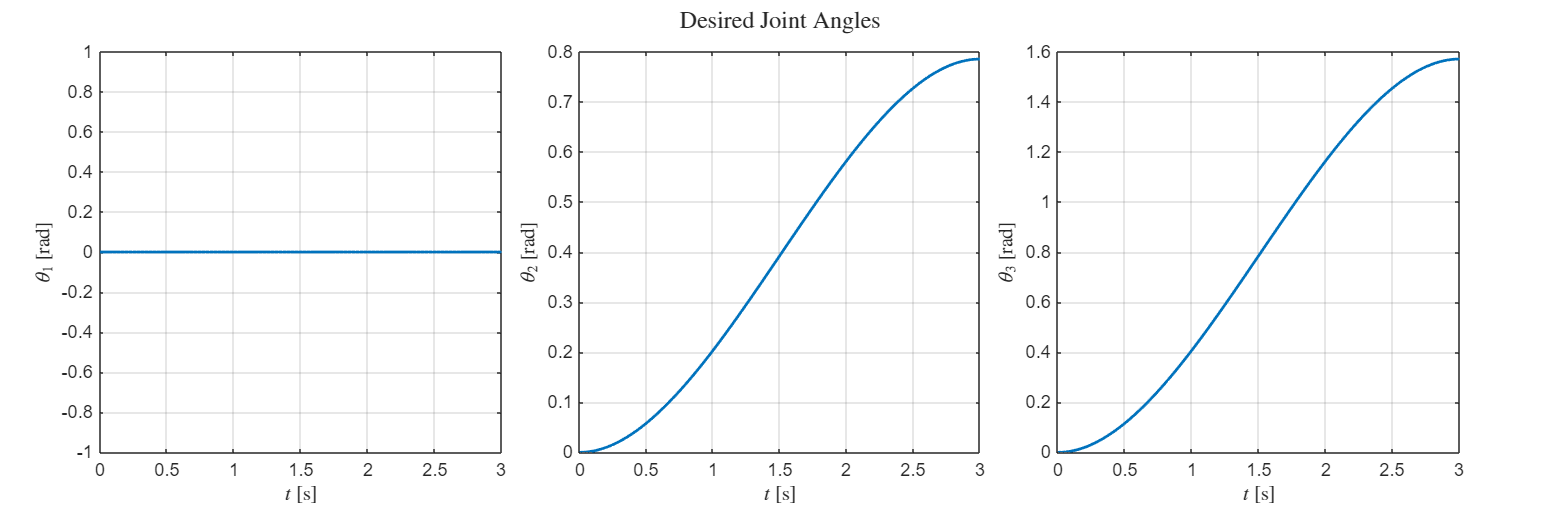

%% --------- Figure 1: Joint Angles ---------
figure()
tiledlayout(1,3, 'TileSpacing','compact', 'Padding','compact')

nexttile
plot(t, theta1_array, 'LineWidth', 1.5); grid on;
ylabel('$\theta_1$ [rad]', 'Interpreter','latex')
xlabel('$t$ [s]', 'Interpreter','latex')

nexttile
plot(t, theta2_array, 'LineWidth', 1.5); grid on;
ylabel('$\theta_2$ [rad]', 'Interpreter','latex')
xlabel('$t$ [s]', 'Interpreter','latex')
% title('Joint Angles', 'Interpreter','latex') % put title in middle

nexttile
plot(t, theta3_array, 'LineWidth', 1.5); grid on;
ylabel('$\theta_3$ [rad]', 'Interpreter','latex')
xlabel('$t$ [s]', 'Interpreter','latex')

sgtitle('Desired Joint Angles', 'Interpreter','latex')
set(gcf, 'Position', [100, 100, 1200, 400]) % wide format

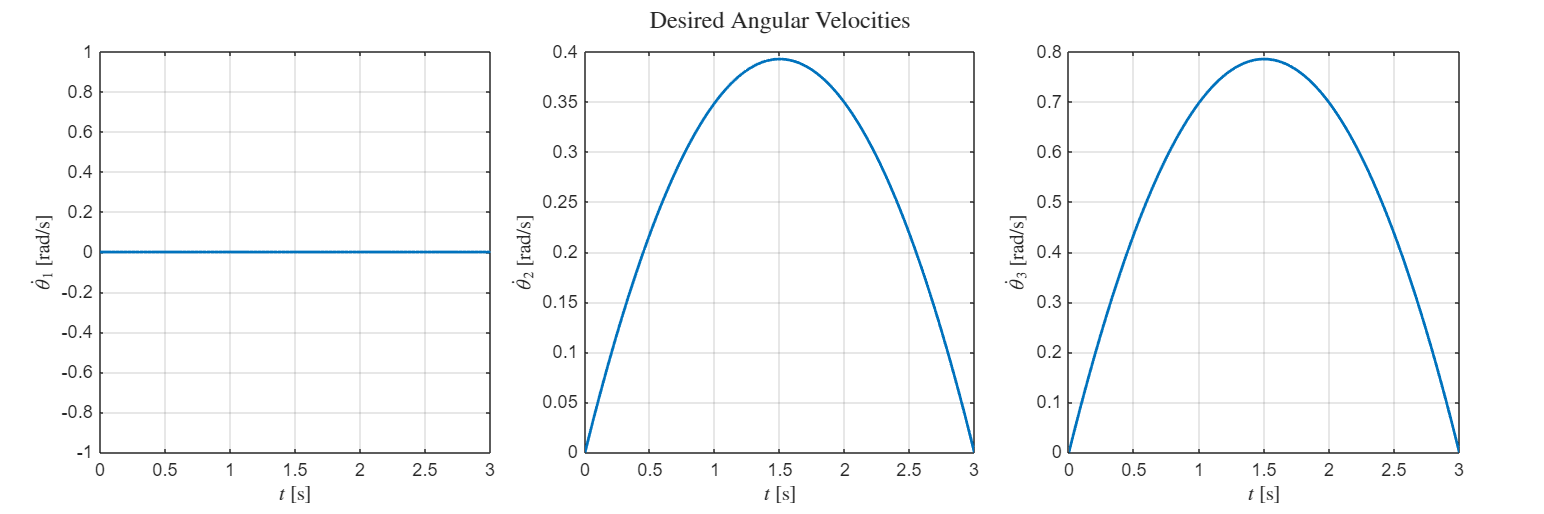



%% --------- Figure 2: Angular Velocities ---------
figure()
tiledlayout(1,3, 'TileSpacing','compact', 'Padding','compact')

nexttile
plot(t, theta_dot_1_array, 'LineWidth', 1.5); grid on;
ylabel('$\dot{\theta}_1$ [rad/s]', 'Interpreter','latex')
xlabel('$t$ [s]', 'Interpreter','latex')

nexttile
plot(t, theta_dot_2_array, 'LineWidth', 1.5); grid on;
ylabel('$\dot{\theta}_2$ [rad/s]', 'Interpreter','latex')
xlabel('$t$ [s]', 'Interpreter','latex')
% title('Angular Velocities', 'Interpreter','latex')

nexttile
plot(t, theta_dot_3_array, 'LineWidth', 1.5); grid on;
ylabel('$\dot{\theta}_3$ [rad/s]', 'Interpreter','latex')
xlabel('$t$ [s]', 'Interpreter','latex')

sgtitle('Desired Angular Velocities', 'Interpreter','latex')
set(gcf, 'Position', [100, 550, 1200, 400]) % place above first

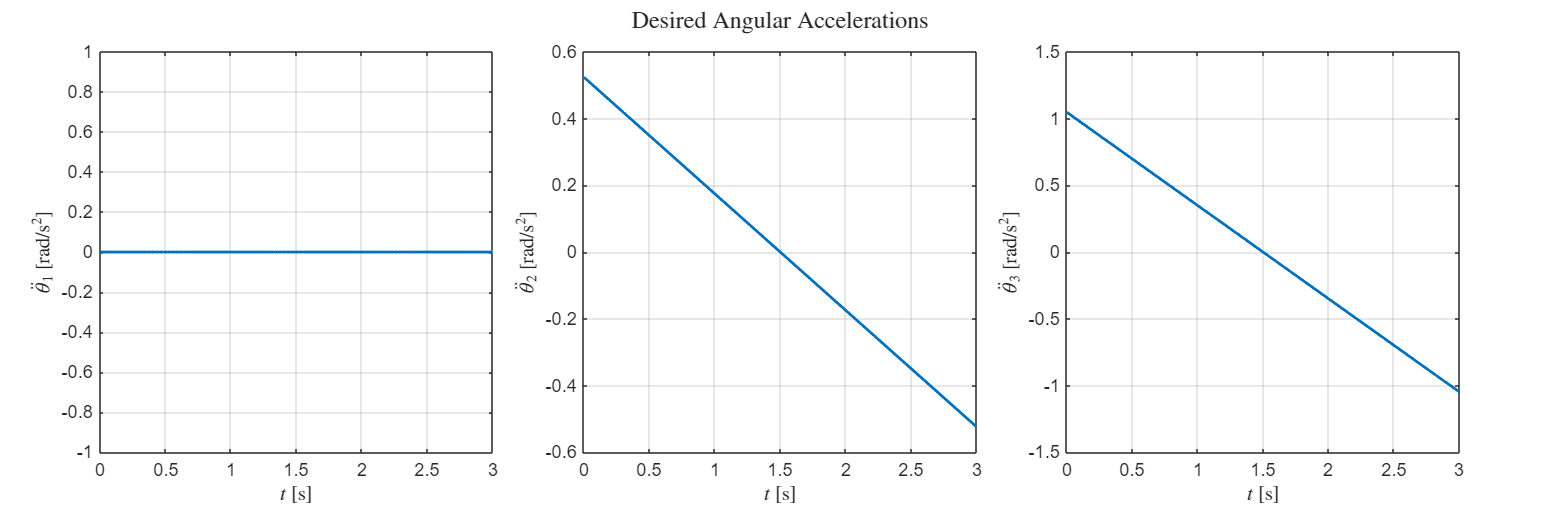



%% --------- Figure 3: Angular Accelerations ---------
figure()
tiledlayout(1,3, 'TileSpacing','compact', 'Padding','compact')

nexttile
plot(t, theta_ddot_1_array, 'LineWidth', 1.5); grid on;
ylabel('$\ddot{\theta}_1$ [rad/s$^2$]', 'Interpreter','latex')
xlabel('$t$ [s]', 'Interpreter','latex')

nexttile
plot(t, theta_ddot_2_array, 'LineWidth', 1.5); grid on;
ylabel('$\ddot{\theta}_2$ [rad/s$^2$]', 'Interpreter','latex')
xlabel('$t$ [s]', 'Interpreter','latex')
% title('Angular Accelerations', 'Interpreter','latex')

nexttile
plot(t, theta_ddot_3_array, 'LineWidth', 1.5); grid on;
ylabel('$\ddot{\theta}_3$ [rad/s$^2$]', 'Interpreter','latex')
xlabel('$t$ [s]', 'Interpreter','latex')

sgtitle('Desired Angular Accelerations', 'Interpreter','latex')
set(gcf, 'Position', [100, 1000, 1200, 400]) % stack on top



rad2deg(theta_i)

ans =      0
     0
     0



rad2deg(theta_f) % desired final joint angles [Shoulder, Thigh, Lower Link]

ans =     45
    45
    70


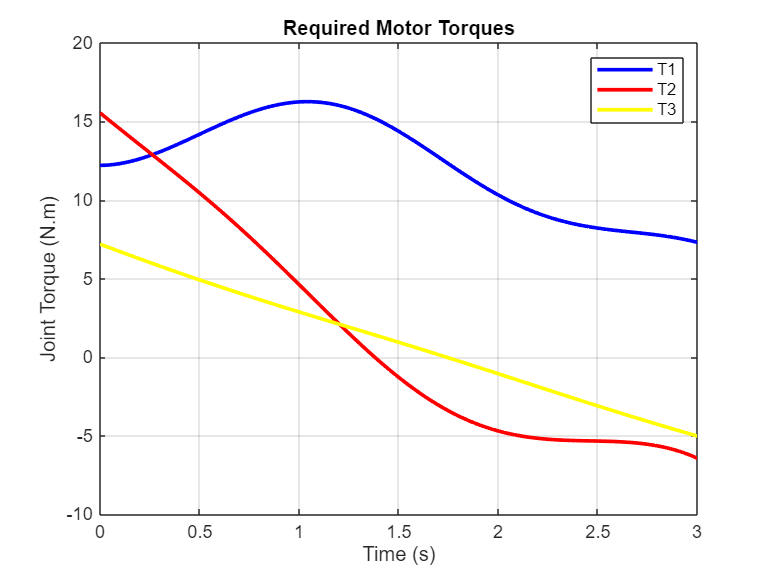

figure()
plot(t,T1,'b',LineWidth=2)
hold on
plot(t,T2,'r',LineWidth=2)
plot(t,T3,'y',LineWidth=2)
xlabel ('Time (s)')
ylabel ('Joint Torque (N.m)')
title('Required Motor Torques')
grid on
legend('T1','T2','T3')

% Calculate maximum and minimum torques
max_T1 = max(abs(T1))*0.737562;

max_T2 = max(abs(T2))*0.737562;

max_T3 = max(abs(T3))*0.737562;

% Display the results
fprintf('Max Torque T1 (shoulder): %.4f lbf-ft\n', max_T1);

Max Torque T1 (shoulder): 11.9932 lbf-ft



fprintf('Max Torque T2 (thigh): %.4f lbf-ft\n', max_T2);

Max Torque T2 (thigh): 11.4651 lbf-ft



fprintf('Max Torque T3 (lower limb): %.4f lbf-ft\n', max_T3);

Max Torque T3 (lower limb): 5.3015 lbf-ft


theta_i = [deg2rad(0) ; deg2rad(0) ; deg2rad(0)] %final joint angles (from inverse kinematics) [rad]

theta_i =      0
     0
     0


theta_f = [deg2rad(45) ; deg2rad(45) ; deg2rad(70)] %final joint angles (from inverse kinematics) [rad]

theta_f =     0.7854
    0.7854
    1.2217


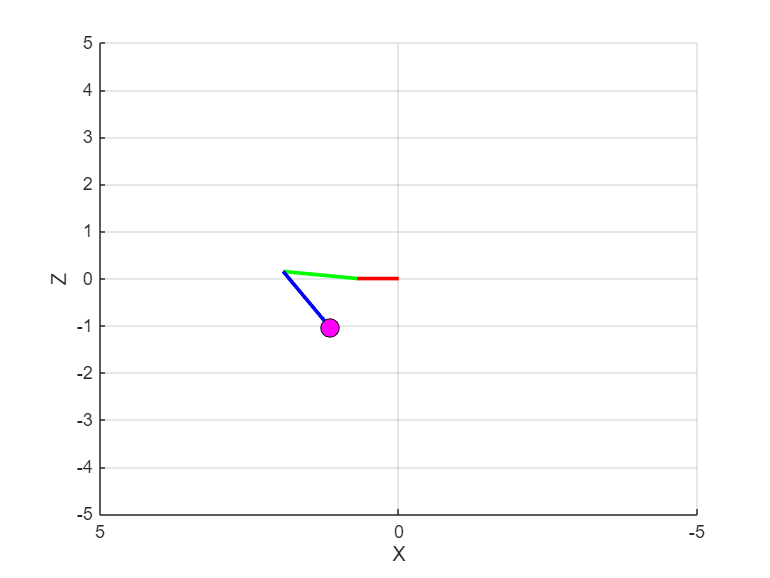

% Call the Visualization Function
eff_point = Visualize3DOFLeg(L1, L2, L3, L4, theta_i, theta_f, T);
% view(3);
view([0 1 0]);

disp(eff_point);

    1.1468
    3.1008
   -1.0447




function O3 = Visualize3DOFLeg(L1, L2, L3, L4, theta_i, theta_f, T)
    Coeff = GenerateTrajectory(theta_i, [0; 0; 0], theta_f, [0; 0; 0], T);
    t = linspace(0, T, 100);

    figure;
    grid on; 
    hold on;
    view(3);
    xlabel('X'); ylabel('Y'); zlabel('Z');
    xlim([-5 5]);
    ylim([-5 5]);
    zlim([-5 5]);

    % Initialize plot objects
    link1 = plot3([0, 0], [0, 0], [0, 0], 'r', 'LineWidth', 2);
    link2 = plot3([0, 0], [0, 0], [0, 0], 'g', 'LineWidth', 2);
    link3 = plot3([0, 0], [0, 0], [0, 0], 'b', 'LineWidth', 2);

    % Initial positions
    O0 = [0;0;0];

    % Rotate Link 1
    for ii = 1:length(t)
        view([186.21 12.58])
        theta1 = Coeff(1,:) * [1; t(ii); t(ii)^2; t(ii)^3];
        A0 = transform(+pi/2, 0, 0, +pi/2);
        A1 = transform(theta1-(pi/2), L1, 0, -pi/2);
        A1 = A0*A1;
        O1 = A1(1:3,4);
        set(link1, 'XData', [O0(1) O1(1)], 'YData', [O0(2) O1(2)], 'ZData', [O0(3) O1(3)]);
        pause(0.01);
    end

    % Rotate Link 2
    for ii = 1:length(t)
        view([90.06 90.00])
        theta2 = Coeff(2,:) * [1; t(ii); t(ii)^2; t(ii)^3];
        A2 = transform(theta2-(pi/2), L2, L3, 0);
        T2 = A1 * A2;
        O2 = T2(1:3,4);
        set(link2, 'XData', [O1(1) O2(1)], 'YData', [O1(2) O2(2)], 'ZData', [O1(3) O2(3)]);
        pause(0.01);
    end

    % Rotate Link 3
    for ii = 1:length(t)
    view([43.78 51.54])
    theta3 = Coeff(3,:) * [1; t(ii); t(ii)^2; t(ii)^3];
    A3 = transform(theta3, 0, L4, 0);
    T3 = T2 * A3;
    O3 = T3(1:3,4);
    set(link3, 'XData', [O2(1) O3(1)], 'YData', [O2(2) O3(2)], 'ZData', [O2(3) O3(3)]);

    % Plot or update end effector point
    if ii == 1
        eff_point = plot3(O3(1), O3(2), O3(3), 'ko', 'MarkerSize', 10, 'MarkerFaceColor', 'm');
    else
        set(eff_point, 'XData', O3(1), 'YData', O3(2), 'ZData', O3(3));
    end

    pause(0.01);
end

end


% The matrices Uij, Dij, Dijk, Di are all aggregated into structures
% because this code also works on symbolic expressions. You are also able
% to change these matrices into 1D,2D or 3D arrays if your expressions are
% numerical

function UijStructure = GenerateUij(AStructure)
    Q = [0 -1 0 0
        1 0 0 0
        0 0 0 0
        0 0 0 0];
    UijStructure = struct();
    for i=1:length(AStructure)
        for j=1:length(AStructure) %taking the derivative wrt this one
            UijStructure(i,j).Matrix = eye(4,4);
            if j > i
                UijStructure(i,j).Matrix = zeros(4,4);
            else
                for k=1:i
                    if k == j
                        UijStructure(i,j).Matrix = UijStructure(i,j).Matrix * Q * AStructure(k).Matrix;
                    else
                        UijStructure(i,j).Matrix = UijStructure(i,j).Matrix * AStructure(k).Matrix;
                    end
                end    
            end
        end
    end
end

function UijkStructure = GenerateUijk(AStructure)
    Q = [0 -1 0 0
        1 0 0 0
        0 0 0 0
        0 0 0 0];
    UijkStructure = struct();
    for i=1:length(AStructure)
        for j=1:length(AStructure) %taking the derivative wrt this one
            for k=1:length(AStructure) %taking the derivative wrt this one
                UijkStructure(i,j,k).Matrix = eye(4,4);
                if (j > i) || (k > i)
                    UijkStructure(i,j,k).Matrix = zeros(4,4);
                else
                    for p=1:i
                        if (p == j) || (p == k)
                            if j == k %special case: double derivative
                                UijkStructure(i,j,k).Matrix = UijkStructure(i,j,k).Matrix * Q * Q * AStructure(p).Matrix;
                            else
                                UijkStructure(i,j,k).Matrix = UijkStructure(i,j,k).Matrix * Q * AStructure(p).Matrix;
                            end
                        else
                            UijkStructure(i,j,k).Matrix = UijkStructure(i,j,k).Matrix * AStructure(p).Matrix;
                        end
                    end    
                end
            end
        end
    end
end

function DijStructure = GenerateDij(UijStructure,JStructure)
    DijStructure = struct();
    n = length(JStructure);
    for i=1:n
        for j=1:n
            DijStructure(i,j).Matrix = 0;
            for p=max(i,j):n
                DijStructure(i,j).Matrix = DijStructure(i,j).Matrix+trace(UijStructure(p,j).Matrix*JStructure(p).Matrix*transpose(UijStructure(p,i).Matrix));
            end
        end
    end
end

function DijkStructure = GenerateDijk(UijStructure,UijkStructure,JStructure)
    DijkStructure = struct();
    n = length(JStructure);
    for i=1:n
        for j=1:n
            for k=1:n
                DijkStructure(i,j,k).Matrix = 0;
                for p=max(i,j):n
                    DijkStructure(i,j,k).Matrix = DijkStructure(i,j,k).Matrix+trace(UijkStructure(p,j,k).Matrix*JStructure(p).Matrix*transpose(UijStructure(p,i).Matrix));
                end
            end
        end
    end
end

function DiStructure = GenerateDi(m_vec,g_vec,UijStructure,rStructure)
    DiStructure = struct();
    n = length(m_vec);
    for i=1:n
        DiStructure(i).Matrix = 0;
        for p=1:n
            DiStructure(i).Matrix = DiStructure(i).Matrix + (-m_vec(p)*transpose(g_vec)*UijStructure(p,i).Matrix*rStructure(p).Matrix);
        end
    end
end

function CoriolisForce = FindCoriolisForce(Dijk,theta_dot_vec)
%computes the inner two sums in the coriolis force equation to return an
%nx1 vector.
    n = length(theta_dot_vec);
    CoriolisForce = struct();
    for i=1:n
        CoriolisForce(i).Matrix = 0;
        for j=1:n
            for k=1:n
                CoriolisForce(i).Matrix = CoriolisForce(i).Matrix+Dijk(i,j,k)*theta_dot_vec(j)*theta_dot_vec(k);
            end
        end
    end
end 

function Coeff = GenerateTrajectory(theta_i, theta_dot_i, theta_f, theta_dot_f, T)
    A = [1 0 0 0
          0 1 0 0 
          1 T T^2 T^3
          0 1 2*T 3*T^2];
    b1 = [theta_i(1); theta_dot_i(1); theta_f(1); theta_dot_f(1)];
    Coeff1 = transpose(A\b1);
    b2 = [theta_i(2); theta_dot_i(2); theta_f(2); theta_dot_f(2)];
    Coeff2 = transpose(A\b2);
    b3 = [theta_i(3); theta_dot_i(3); theta_f(3); theta_dot_f(3)];
    Coeff3 = transpose(A\b3);
    Coeff = [Coeff1; Coeff2; Coeff3];
end

function A = transform(theta, d, a, alpha)
% transform generate a 4X4 matix based off DH parameters
% from n to n+1
% this computation will be in terms of radians

A = [cos(theta), -sin(theta)*cos(alpha), sin(theta)*sin(alpha), a*cos(theta);
    sin(theta), cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta);
    0, sin(alpha), cos(alpha), d;
    0, 0, 0, 1];

end